# **Course Project in Computational Mathematics**

## **Direct fast method for solving the SoLE of the anisotropic diffusion equation** 

### Double fast sine conversion 

Consider the anisotropic diffusion equation supplemented by the Dirichlet condition in the unit square. 

## 
$$-\frac{\partial^2 }{\partial x^2 }u\left(x,y\right)-3\;\frac{\partial^2 }{\partial y^2 }u\left(x,y\right)\;+u\left(x,y\right)=f\left(x,y\right),\;\mathrm{in}\;V=\left(0,1\right)\;\&\;{\;u\left(x,y\right)|}_G =0\;$$


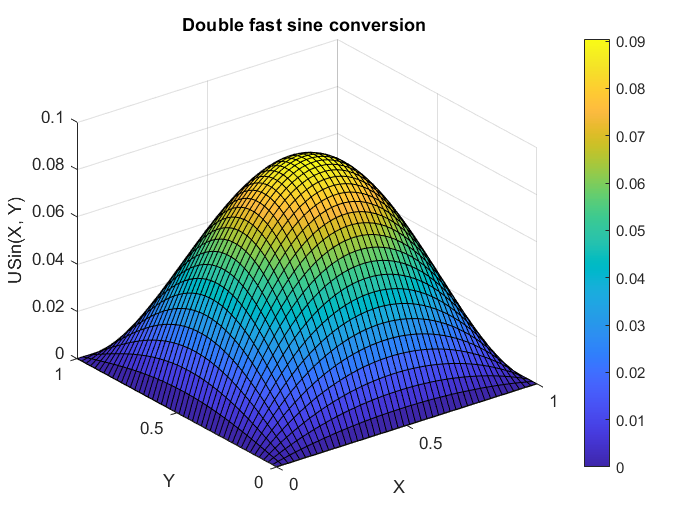

clc;
clear all;

steps = 45; % quantity of steps for grid
step = 1 / steps;  % step of grid

%% constructing right part of equation
fSin = zeros((steps - 1), (steps - 1));
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
%         fSin(ix, iy) = 32 * step.^3 * (ix * (1 - ix * step) + iy * (1 - iy * step));
%         fSin(ix, iy) = step.^4 * ix.^2;
        fSin(ix, iy) = 3 * step.^2 * sin(pi * ix * step);
    end
end

% multiply by W^(-1)
fSin = fSin';
uSin = idst(fSin);
uSin = uSin';
uSin = idst(uSin) / step.^2;

%% reverse matrix of diag(Spectrum)
lambda = zeros((steps - 1), (steps - 1));
for m = 1 : steps - 1
    for k = 1 : steps - 1
        lambda(k, m) = step.^2 / (4 * (sin(pi * k * step * 0.5)).^2 + 12 * ...
        (sin(pi * m * step * 0.5)).^2 + step.^2);
    end
end
uSin = lambda .* uSin;

% multiply by W
uSin = uSin';
uSin = dst(uSin);
uSin = uSin';
uSin = dst(uSin);

%% plotting solution
[X, Y] = meshgrid(0 : step : 1, 0 : step : 1);
USin = zeros(steps + 1, steps + 1);
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
        USin(ix + 1, iy + 1) = uSin(ix, iy);
    end
end
surf(X, Y, USin);
title('Double fast sine conversion ');
ylabel('Y'), xlabel('X'), zlabel('USin(X, Y)');
colorbar;

### Jacobi method

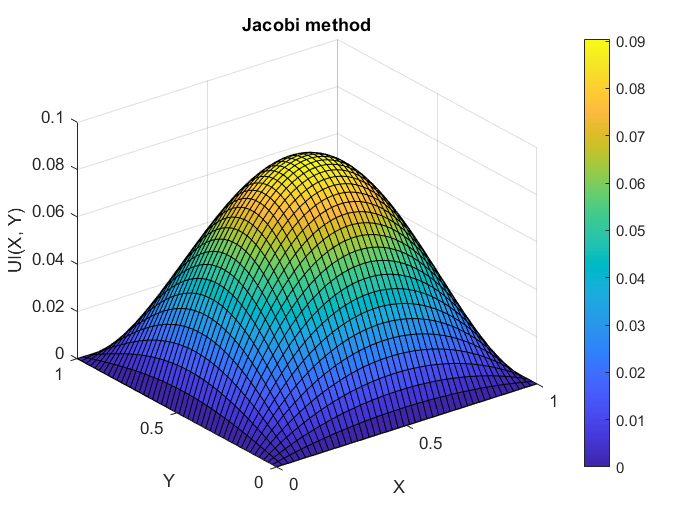

%% constructing right part of equation
fI = zeros(1, (steps - 1) * (steps - 1));
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
%         fI(1, (iy - 1) * (steps - 1) + ix) = 32 * step.^3 * (ix * (1 - ix * step) + iy * (1 - iy * step));
%         fI(1, (iy - 1) * (steps - 1) + ix) = step.^4 * ix.^2;
        fI(1, (iy - 1) * (steps - 1) + ix) =  3 * step.^ 2 * sin(pi * ix * step);
    end
end

%% constructing reverse diag part of matrix
reverseD = zeros(1, (steps - 1) * (steps - 1));
for m = 1 : steps - 1
    for k = 1 : steps - 1
        reverseD(1, (m - 1) * (steps - 1) + k) = 1 / (8  + step.^2);
    end
end

%% constructing other part of matrix
negative3E = -3 * eye(steps - 1);
C = zeros(steps - 1);
for i = 1 : (steps - 1)
    for j = 1 : (steps - 1)
        if i - j == 1 || j - i == 1
            C(i, j) = -1;
        end
    end
end
A = zeros((steps - 1) * (steps - 1), (steps - 1) * (steps - 1));
for i = 1 : (steps - 1)
    for j = 1 : (steps - 1)
        if i - j == 1 || j - i == 1
            A((i - 1) * (steps - 1) + 1 : i  * (steps - 1), (j - 1) * (steps - 1) + 1 : j  * (steps - 1) ) = negative3E;
        end
        if i == j 
            A((i - 1) * (steps - 1) + 1 : i  * (steps - 1), (j - 1) * (steps - 1) + 1 : j  * (steps - 1) ) = C;
        end
    end
end

%% Jacobi method
uJ = zeros(1, (steps - 1) * (steps - 1));
itterations =4000;
for k = 1 : itterations
    uJ = reverseD .* fI - reverseD .* (uJ * A);
end

%% plotting solution
UJ = zeros(steps + 1, steps + 1);
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
        UJ(ix + 1, iy + 1) = uJ(1, (iy - 1) * (steps - 1) + ix);
    end
end
surf(X, Y, UJ);
title('Jacobi method');
ylabel('Y'), xlabel('X'), zlabel('UI(X, Y)');
colorbar;

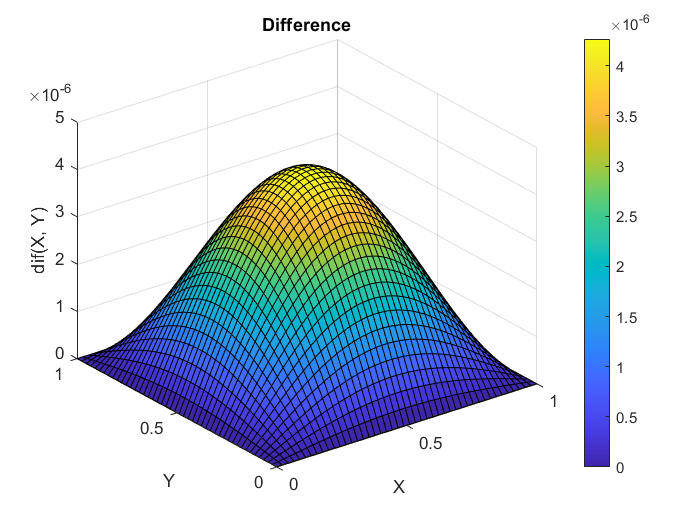

dif = USin - UJ;
surf(X, Y, dif);
title('Difference');
ylabel('Y'), xlabel('X'), zlabel('dif(X, Y)');
colorbar;

### Exact solution

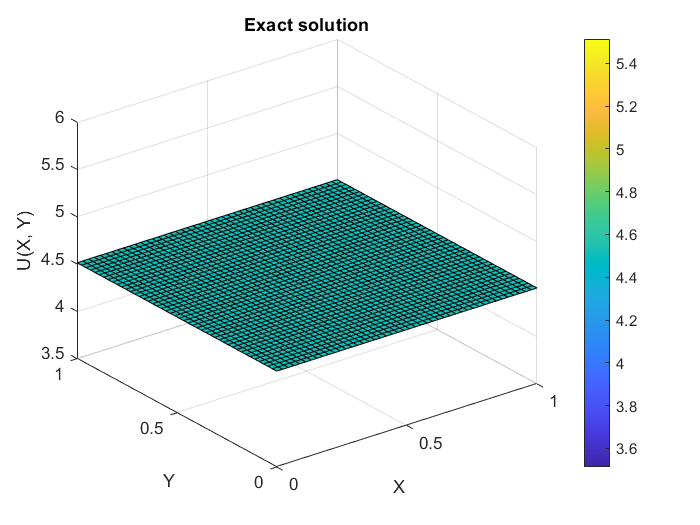

Const = (3 * cosh((pi.^2 + 1) / 3) / (pi.^2 + 1) - 3 / (pi.^2 + 1)) / sinh((pi.^2 + 1) / 3);
U = sin(pi * X) * (-3 * cosh((pi.^2 + 1) * Y / 3) / (pi.^2 + 1) + 3 / (pi.^2 + 1) + Const * sinh((pi.^2 + 1) * Y / 3));
surf(X,Y,U);
title('Exact solution');
ylabel('Y'), xlabel('X'), zlabel('U(X, Y)');
colorbar;